Calcular los modos de DMD:

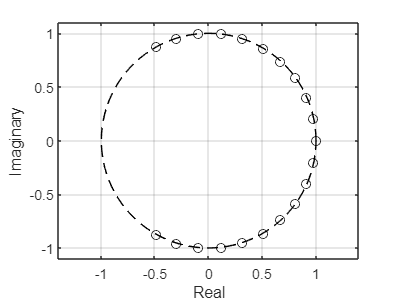

load("CYLINDER_ALL.mat", "VORTALL")
Avortex1 = VORTALL(:,1:end-1);
Avortex2 = VORTALL(:,2:end);
%Empiezo haciendo el SVD
%VORTALL ya está organizado.
[U, S, V] = svd(Avortex1, "econ");

r = 21;
U = U(:, 1:r);
S = S(1:r,1:r);
V = V(:, 1:r);
Awierd = U'*Avortex2*V*inv(S);

[W,eigs] = eig(Awierd);
Phi = Avortex2*V*inv(S)*W;

theta = (0:1:100) *2*pi/100;
plot(cos(theta),sin(theta),"k--") % plot unit circle
hold on, grid on
scatter(real (diag (eigs)),imag (diag(eigs)),"ok")
axis ([-1.1 1.1 -1.1 1.1]);
axis equal;
xlabel("Real")
ylabel("Imaginary")